# sæt 2023 olibolib

## Q20

## Q2




clf;
clear all;
clc;
%      Første model brugt
s = tf('s');
syms C L R C 
% numG =  R;                        % numerator
% denG =  C*L*s^2+R*C+1; % denominator

Error using sym>tomupad
Unable to convert 'tf' to 'sym'.

Error in sym (line 273)
                S.s = tomupad(x);

Error in sym/privResolveArgs (line 1073)
                    argout{k} = sym(arg);

Error in 

% 
% G = numG/denG;



## Q3

% løft Wc så den ligger ved Wc
kp=db2mag(15.33)

kp = 5.8412

% jeg skal hæve den derfor skal det være invers af den aflæste værdi i
% plottet.


## Q5 (13)

% 
clf;
clear all;
clc;
%      Første model brugt
s = tf('s');
syms a
wc= 25;
mag=db2mag(2.5)

mag = 1.3335

eqn = mag*sqrt(a)==1; %% 


sol = solve(eqn,a);
var = vpa(sol); % numerical approximate
alpha1 = double(var)

alpha1 = 0.5623

% tidskonstant i LEAD er 1/sqrt(alpha)
taud = 1/(sqrt(alpha1)*wc)

taud = 0.0533



Cd = (taud*s + 1)/(alpha1*taud*s + 1)

Cd =
 
  0.05334 s + 1
  -------------
   0.03 s + 1
 
Continuous-time transfer function.
Model Properties


## Q6

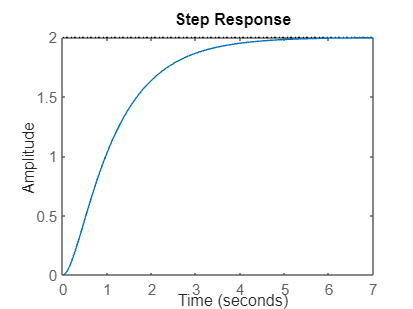

% 
clf;
clear all;
clc;
%      Første model brugt

s = tf('s');

numG = 8;                        % numerator
denG = (s+1)*(s+4); % denominator

G = numG/denG;
step(G)


% Gstep3 = (3/s)*G;
% step(Gstep3)
% stepinfo(Gstep3)

ge= 1/(1+G);
ess=freqresp(s*ge*3/s,0)

ess = 1


p = pole(G)

p =     -4
    -1


z = zero(G)


z =

  0×1 empty double column vector



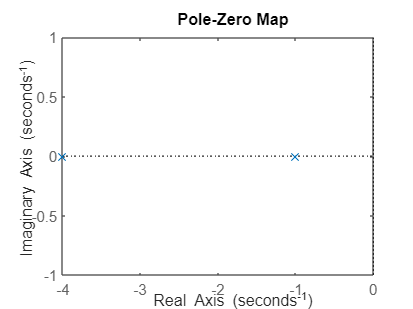

pzplot(G)

## Q 7

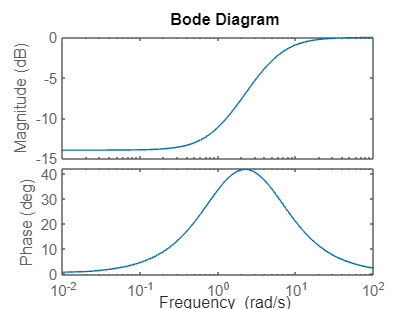

% find bode plottet
% 
clf;
clear all;
clc;
%      Første model brugt

s = tf('s');

numG = (s+1);                        % numerator
denG = (s+5); % denominator

G = numG/denG;
bode(G)

## Q8

% find bode plottet
% 
clf;
clear all;
clc;
%      Første model brugt

s = tf('s');

numG1 = (4);                        % numerator
denG1 = (s+10); 
G1 = numG1/denG1;

numG2 = (1);                        % numerator
denG2 = (s+2); 
G2 = numG2/denG2;
numG3 = (s+2);                        % numerator
denG3 = (s+10); 
G3 = numG3/denG3;

G23 = G2*G3;
G231 = G23+G1;

Gcl = G231/(1-G231)

Gcl =
 
     5 s^5 + 170 s^4 + 2120 s^3 + 11600 s^2 + 26000 s + 20000
  ---------------------------------------------------------------
  s^6 + 39 s^5 + 594 s^4 + 4440 s^3 + 16800 s^2 + 30000 s + 20000
 
Continuous-time transfer function.
Model Properties



stepinfo(Gcl)

ans = struct with fields:
         RiseTime: 0.4394
    TransientTime: 0.7824
     SettlingTime: 0.7824
      SettlingMin: 0.9045
      SettlingMax: 0.9993
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9993
         PeakTime: 1.4644


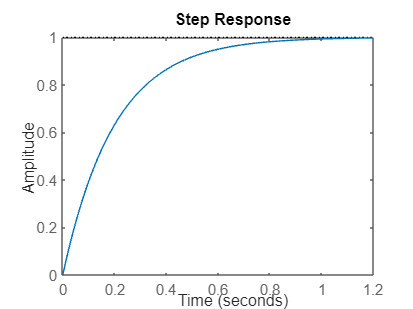


step(Gcl)

freqresp(Gcl,0)

ans = 1


g1 = 4/10;
g2 = 1/2;
g3 = 2/10;

yt=(g2*g3+g1)

yt = 0.5000

y01=yt/(1-yt)

y01 = 1

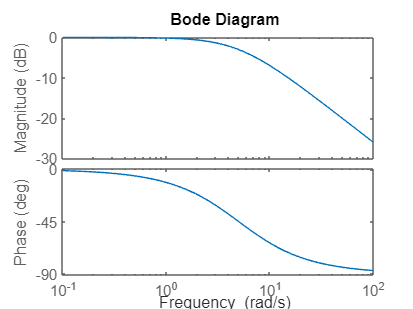


bode(Gcl)



freqresp(Gcl*s,0)

ans = 0

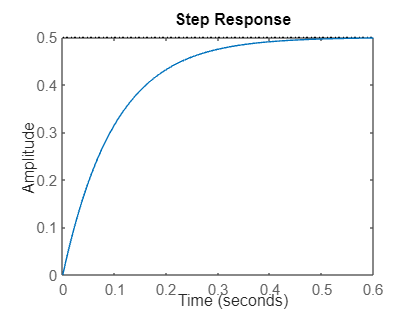


step(G231);

## Q10



% lavet i maple



## Q11

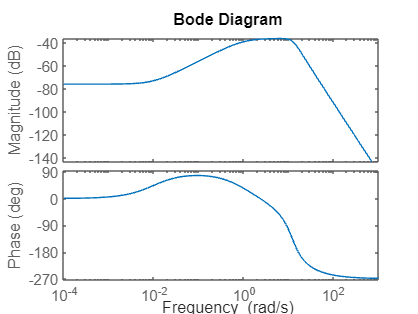

% find bode plottet
% 
clf;
clear all;
clc;
%      Første model brugt

s = tf('s');

numG = 24*(s+0.01);                        % numerator
denG = (s+1)*(s^2+10.5*s+150)*(s+10); % denominator

G = numG/denG;
bode(G)

wc = 15.4744;
ym=75;
[mag, phase,wout] = bode(G);
mag = squeeze(mag);
phase = squeeze(phase);
magr2=(mag/max(mag)).^2;
db3 = interp1(magr2,[wout, phase, mag], 0.5, 'spline');

mag1=db3(1,3)

mag1 = 0.0110

phase1=db3(1,2)

phase1 = 35.4354



a = 0.01;
% 
% td = 1/(wc*sqrt(a));
% phim=1
% phi_i = phase - ym + 180 + 
% 


## Q11 - 2.nd try

clf;
clear all;
clc;
%      Første model brugt
w = linspace(1e-4,120,5000);
s = tf('s');

numG = 24*(s+0.01);                        % numerator
denG = (s+1)*(s^2+10.5*s+150)*(s+10); % denominator

G = numG/denG;
bode(G)

wc = 15.4744;
ym=75;
[mag, phase] = bode(G,w);
mag = squeeze(mag);
phase = squeeze(phase);
a = 0.01;
Ym = 75;
Ni=5;
phiCd = asind((1-a)/(1+a))

phiCd = 78.5788

phi_i= -atand(1/Ni);
Gwc = -180 + Ym - phiCd - phi_i

Gwc = -172.2689


% vi skal bare her finde at phase er lig phasen. 



## Q13

clf;
clear all;
clc;
%      Første model brugt

s = tf('s');
syms x1 x2 u s y

eqn1 = s*x1 == -2*x1 + x2 + u

$$eqn1 = s\,x_{1}=u-2\,x_{1}+x_{2}$$

eqn2 = s*x2 == -3*x2 + 3*u

$$eqn2 = s\,x_{2}=3\,u-3\,x_{2}$$

eqn3 = y == x2

$$eqn3 = y=x_{2}$$


solx1= solve(eqn1, u,x1)

solx1 = struct with fields:
     u: -x2
    x1: 0


solx2 = solve(eqn2,x2)

$$solx2 = \frac{3\,u}{s+3}$$

solve = solve(eqn3,x2)

$$solve = y$$

## Q14

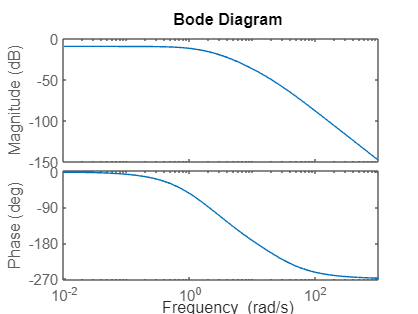

clf;
clear all;
clc;
%      Første model brugt
w = linspace(1e-4,120,10000);
s = tf('s');

numG = 10;                        % numerator
denG = (0.25*s+1)*(s^2+25*s+30); % denominator

G = numG/denG;
bode(G)

[mag,phase] = bode(G,w);
mag = squeeze(mag);
phase = squeeze(phase);
a=0.1;
Ni=2;
ym=55;
phCi = atand(-1/Ni);
phCm = asind((1-a)/(1+a));
Gphas=-180+ym-phCi-phCm

Gphas = -153.3381



% aflæst på Gphas værdien for at få freq. 
p_c =find(phase < Gphas,1,'first');
wc=w(p_c);

tauD=1/(sqrt(a)*wc);
tauI=Ni*(1/wc);
Ci = ((tauI*s+1)/(tauI*s));

Cd = (tauD*s+1)/(tauD*a*s+1);

Kp= abs(freqresp(Ci*Cd*G,wc))

Kp = 0.1110

kp1=1/Kp

kp1 = 9.0074

% Btw Se slides i lektion 8



## Q17    

% Control design 
db2mag(-2.4988)

ans = 0.7500

% peaket på closed loop correspondere med ymax på step respons eller nej vi
% kan se dens max værdi i steppet 


